Number_of_Qubits = 1;
Number_of_Steps = 10;
Step_size = 0.3;
Number_of_walks = 500;
Precision = 1/sqrt(2^Number_of_Qubits);

Walk = Random_Walk(Number_of_Qubits, Number_of_Steps, Step_size, Number_of_walks, Precision)

Walk =    1.0000 + 0.0000i   0.0000 + 0.0000i   1.0000 + 0.0000i   0.0000 + 0.0000i   1.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   1.0000 + 0.0000i   0.0000 + 0.0000i   1.0000 + 0.0000i   0.0000 + 0.0000i   1.0000 + 0.0000i   0.0000 + 0.0000i   1.0000 + 0.0000i   0.0000 + 0.0000i   1.0000 + 0.0000i   0.0000 + 0.0000i   1.0000 + 0.0000i   0.0000 + 0.0000i   1.0000 + 0.0000i   0.0000 + 0.0000i   1.0000 + 0.0000i   0.0000 + 0.0000i   1.0000 + 0.0000i   0.0000 + 0.0000i   1.0000 + 0.0000i   0.0000 + 0.0000i   1.0000 + 0.0000i   0.0000 + 0.0000i   1.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   1.0000 + 0.0000i   0.0000 + 0.0000i   1.0000 + 0.0000i   0.0000 + 0.0000i   1.0000 + 0.0000i   0.0000 + 0.0000i   1.0000 + 0.0000i   0.0000 + 0.0000i   1.0000 + 0.0000i   0.0000 + 0.0000i   1.0000 + 0.0000i   0.0000 + 0.0000i   1.0000 + 0.0000i   0.0000 + 0.0000i
   0.1199 - 0.5725i   0.8111 + 0.0000i   0

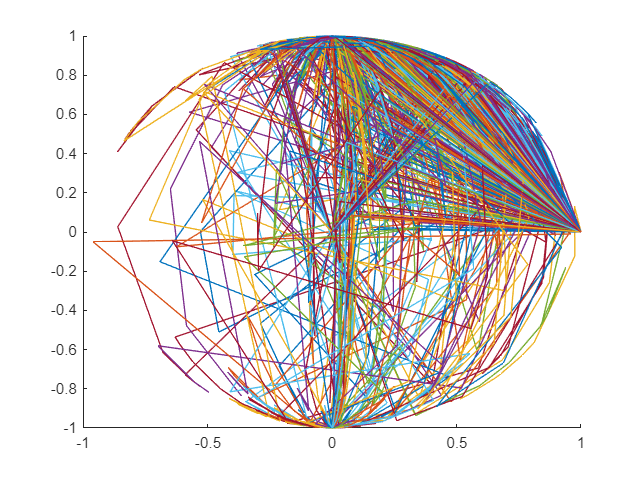


% Plotting for Sanity Check (Only use for 2 dimensions) 

A = any(Walk);

hold on 
for j = 1:2:(2*Number_of_walks)
    if A(1,j) == 1

        X = real(Walk(1:Number_of_Steps,j));
        Y = real(Walk(1:Number_of_Steps,j+1));
        
        plot(X,Y)
    end
end
hold off


% Test_Dimensions = 2^Number_of_Qubits
% Test_Parameters = 2*pi*rand(2*(Test_Dimensions-1),1)
% Test_Step = Step_size * rand(2*(Test_Dimensions-1),1)
% 
% Test_1 = State_Generator(Test_Parameters,Test_Dimensions)
% Test_2_a = Partial_Differentiator(Test_Parameters, Test_Dimensions, 1)
% Test_2_b = Partial_Differentiator(Test_Parameters, Test_Dimensions, 2)
% Test_3 = Random_Walk_Vector(Test_Dimensions)
% Test_4 = Metric_Generating_Function(Test_Dimensions, Test_1, Test_Parameters)
% Test_5_a = Step_Generator(Step_size, Test_Dimensions, Test_Parameters, Test_1)
% [Test_5_b, Test_5_c] = eig(Test_4)


function SG = State_Generator(Parameters, Dimensions)
    
    State = zeros(Dimensions,1);
    Array_of_Sines = zeros(Dimensions-1,1);
    
    for z = 1:(Dimensions-1)

        Array_of_Sines(z,1) = sin(Parameters(z,1));
    end 

    Projective_Coordinate = 1;

        for n = 1:(Dimensions-1)
            if n == 1 
                State(n,:) = exp(1i*Parameters(Dimensions+n-1))*cos(Parameters(n));
            else
            for m = 1:(n-1)
          
                Projective_Coordinate = Projective_Coordinate*Array_of_Sines(m);
            end
    
            State(n,1) = exp(1i*Parameters(Dimensions+n-1))*Projective_Coordinate*cos(Parameters(n));
            end
        end

    State(Dimensions,1) = prod(Array_of_Sines);
    SG = State;
end

function PD = Partial_Differentiator(Initial_Parameters, Dimensions, Chosen_Parameter)

    Initial_State = State_Generator(Initial_Parameters, Dimensions);
    Derivative_State = zeros(Dimensions,1);

    if Chosen_Parameter > (Dimensions-1)
        for s=1:(Dimensions-1)
            if s== Chosen_Parameter

                Derivative_State(s) = 1i*Initial_State(s);
            else 

                Derivative_State(s) = 0;
            end
         end

    else
        for x = 1:(Dimensions-1)

            if x == Chosen_Parameter 
                Derivative_State(x) = (Initial_State(x)/cos(Initial_Parameters(x)))*(-1)*sin(Initial_Parameters(x));
    
            elseif x < Chosen_Parameter
    
                Derivative_State(x) = 0;
    
            elseif x > Chosen_Parameter
    
                Derivative_State(x) = (Initial_State(x)/sin(Initial_Parameters(x)))*cos(Initial_Parameters(x));
            end
        end

        Derivative_State(Dimensions,1) = (Initial_State(Dimensions)/sin(Initial_Parameters(Dimensions)))*cos(Initial_Parameters(Dimensions));
    end

PD = Derivative_State;

end

function RWV = Random_Walk_Vector(Dimensions)
    
    Array_Dimensions = 2*(Dimensions-1);
    Walker = zeros(Array_Dimensions,1);
    Local_Vector = randn(Array_Dimensions,1);
    Summated_Vector = 0;
    Walker = zeros(Array_Dimensions,1);

    for m = 1:Array_Dimensions

    Summated_Vector = Summated_Vector + Local_Vector(m)^2 ;

    end

    for n = 1:Array_Dimensions

        Walker(n) = Local_Vector(n)/sqrt(Summated_Vector);

    end

RWV = Walker;
end 

function MGF = Metric_Generating_Function(Dimensions, First_State, Initial_Parameters)

    FS_Matrix_1 = zeros(Dimensions,Dimensions);
    FS_Matrix_2 = zeros(Dimensions,Dimensions);

    for i = 1:2*(Dimensions-1) 
        for j = 1:2*(Dimensions-1)
            
            FS_Matrix_1(i,j) = dot(Partial_Differentiator(Initial_Parameters, Dimensions, i), Partial_Differentiator(Initial_Parameters, Dimensions, j)) - (dot(Partial_Differentiator(Initial_Parameters, Dimensions, i),First_State)) * (dot(First_State, Partial_Differentiator(Initial_Parameters, Dimensions, j)));
            FS_Matrix_2(j,i) = FS_Matrix_1(i,j);
        end
    end

    MGF = (FS_Matrix_1 + FS_Matrix_2)*0.5;
end



function SG = Step_Generator(Step_Size, Dimensions, Initial_Parameters, First_State)

    Array_Dimensions = 2*(Dimensions - 1);
    pre_Theta = zeros(Array_Dimensions:1);
 
    u = Random_Walk_Vector(Dimensions);
    g = Metric_Generating_Function(Dimensions, First_State, Initial_Parameters);
    [V, h] = eig(g);
    
        for i = 1:Array_Dimensions

            if h(i,i) == 0 

                pre_Theta(i,:) = 0;
            else

            pre_Theta(i,:) = (Step_Size / sqrt(h(i,i))) * u(i);
            end

        end 

  SG = V*pre_Theta;

end

function R = Random_Walk(Number_of_Qubits, Number_of_Steps, Step_size, Number_of_walks, Precision)

    Dimension_of_Hilbert_Space = 2^(Number_of_Qubits);
    Successful_Walks = zeros(Dimension_of_Hilbert_Space*Number_of_walks, Number_of_Steps);
   
    for n = 1:Dimension_of_Hilbert_Space:Dimension_of_Hilbert_Space*(Number_of_walks + 1)

        State_Vectors = zeros(Dimension_of_Hilbert_Space, Number_of_Steps);
        State_Parameters = zeros( 2*(Dimension_of_Hilbert_Space - 1), Number_of_Steps);

        Initial_Parameters= zeros(2*(Dimension_of_Hilbert_Space -1),1);
        Initial_State = State_Generator(Initial_Parameters, Dimension_of_Hilbert_Space);
    
        State_Vectors(:,1) = Initial_State;
        State_Parameters(:,1) = Initial_Parameters;
        State_Parameters(:,2) = Initial_Parameters + (pi/2)*rand(2*(Dimension_of_Hilbert_Space -1),1);
        State_Vectors(:,2) = State_Generator(State_Parameters(:,2), Dimension_of_Hilbert_Space);
        for t = 3:Number_of_Steps

            S = State_Parameters(:,t-1) + Step_Generator(Step_size, Dimension_of_Hilbert_Space, State_Parameters(:,t-1), State_Vectors(:,t-1));
            % 
            % if S >= 2*pi
            % 
            %     S = S - 2*pi;
            % 
            %     State_Parameters(:,t) = S ; 
            % 
            %     State_Vectors(:,t) = State_Generator(State_Parameters(:,t), Dimension_of_Hilbert_Space);
            % 
            %     Distance = acos(dot(State_Vectors(:,1), State_Vectors(:,t)));
            % 
            % else

            State_Parameters(:,t) = S;
           
            State_Vectors(:,t) = State_Generator(State_Parameters(:,t), Dimension_of_Hilbert_Space);
            
            Distance = acos(dot(State_Vectors(:,1), State_Vectors(:,t)));

            %end

          if abs(pi/2 - Distance) <= Precision
              
              for j = 1:Dimension_of_Hilbert_Space
              Successful_Walks(n-1+j,:) = State_Vectors(j,:);
              end
          end

        end 

        Final_Distance = acos(dot(State_Vectors(:,1), State_Vectors(:,Number_of_Steps)));

          if abs(pi/2 - Final_Distance) <= Precision
              
              for j = 1:Dimension_of_Hilbert_Space
              Successful_Walks(n-1+j,:) = State_Vectors(j,:);
              end
          end 
    end

    R = Successful_Walks';   
end